# Numerische Lösung von Anfangswertproblemen

Eine unbekannte Funktion

clear

## 1. Grundlagen

F = @(x, y) sin(2 * pi * x) + y;

Exakte Lösung

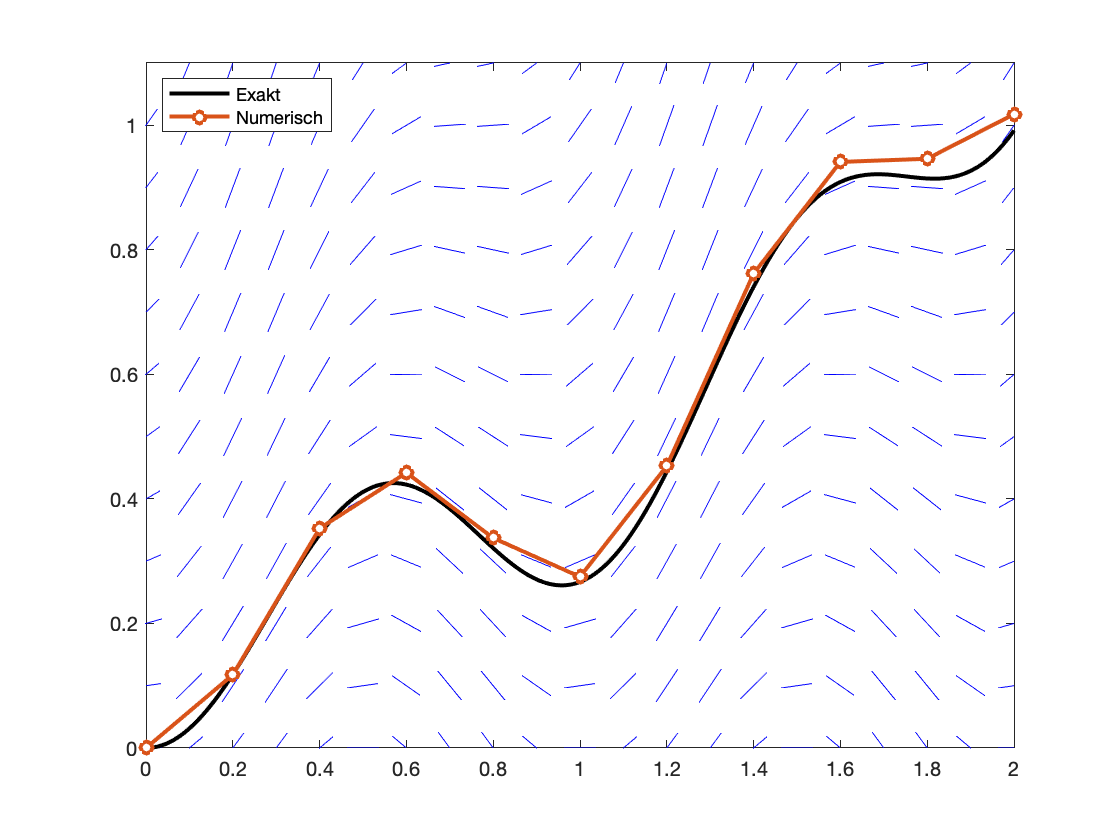

y = @(x) (2*exp(x)*pi - 2*pi*cos(2*pi*x) - sin(2*pi*x))/(1 + 4*pi^2);
xR = linspace(0, 2, 500);
yR = y(xR);

[x, y] = halbschritt(F, [0, 2], 0.2, 0); 

plotSlopeField(F, [0, 2], [0, 1.1], 0.1)
hold on
p1  = plot(xR, yR, 'LineWidth', 2, 'Color', 'k');
p2 = plot(x, y, '-o', 'MarkerFaceColor', 'w' ,'LineWidth', 2);
legend([p1, p2], 'Exakt', 'Numerisch', 'Location', 'northwest')
xlim([0, 2])
ylim([0, 1.1])
hold off
exportgraphics(gca, '../numerische-loesung.pdf')

Lösungsschar

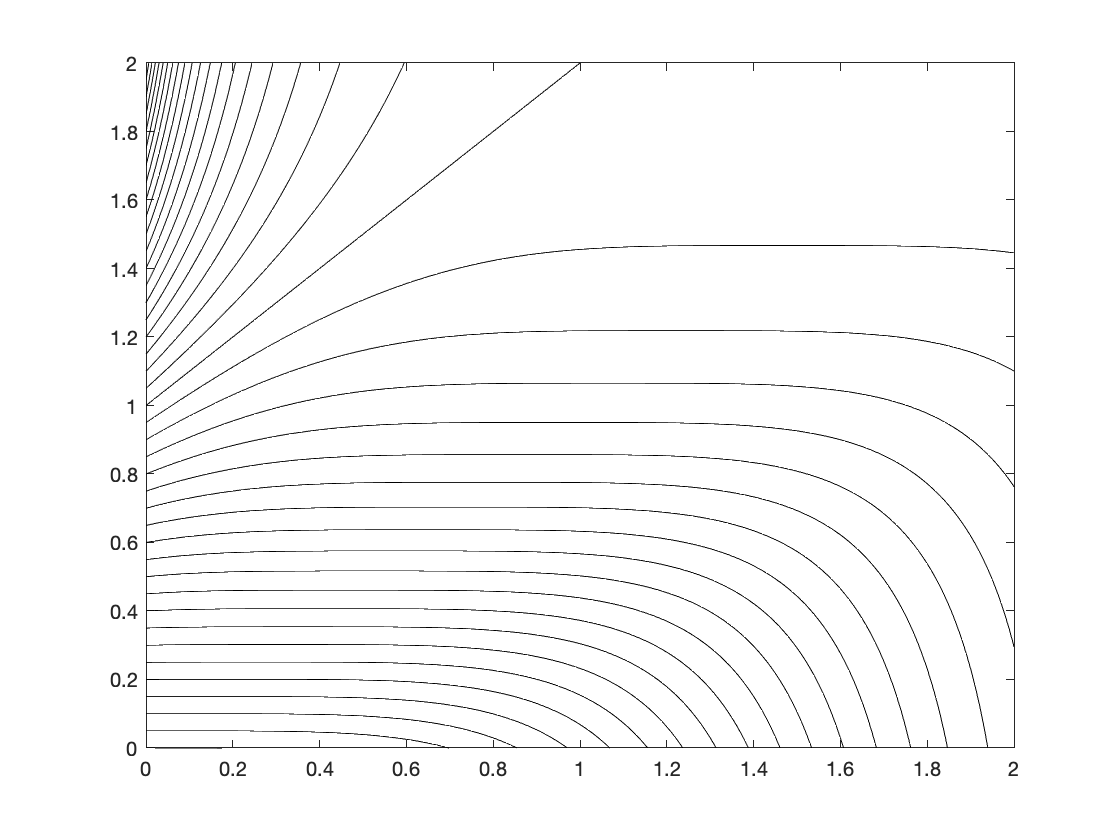

F = @(x, y) (y-x)^3;
for y0 = 0:0.05:3    
    [x, y] = halbschritt(F, [0, 2], 0.01, y0);
    plot(x, y, 'k')
    hold on
end
hold off
xlim([0, 2])
ylim([0, 2])

## 2. Euler-Verfahren

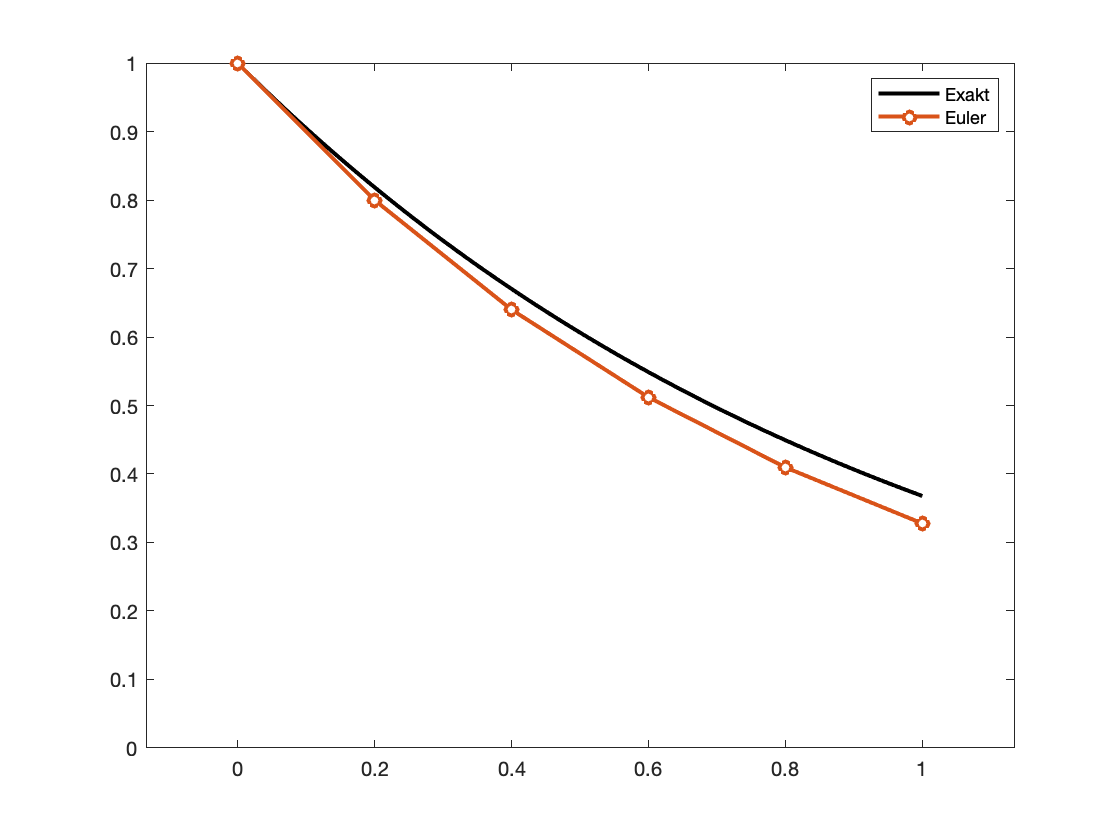

F = @(x, y) -y;

y = @(x) exp(-x);
xR = linspace(0, 1, 100);
yR = y(xR);

[x, y] = euler(F, [0, 1], 0.2, 1); 

plot(xR, yR, 'LineWidth', 2, 'Color', 'k')
hold on
plot(x, y, '-o', 'MarkerFaceColor', 'w' ,'LineWidth', 2)
xlim([0, 1])
ylim([0, 1])
hold off
legend('Exakt', 'Euler')
axis equal